clear
load 20210305-RC_Chirp40v150kHz_T2s.mat
A1=A;
B1=B;
N=Length;
dt=Tinterval

dt = 1.0000e-06

fs=1/dt

fs = 1.0000e+06

t=(0:N-1)*dt;
df=fs/N;
f=(0:df:fs-df);
load 20220401-RLC_Chirp1v300kHz_T2s.mat
A2=A;
B2=B;


R1=47;
C1=2.2e-6;

R2=220;
C2=4.7e-6;
L2=1e-3;

num1=1/(R1*C1)

num1 = 9.6712e+03

den1=[1 num1]

den1 = 1.0e+03 *

    0.0010    9.6712


sys=tf(num1,den1)


sys =
 
    9671
  --------
  s + 9671
 
Continuous-time transfer function.
Model Properties



num2=[R2/L2 0]

num2 =       220000           0


den2=[1 R2/L2 1/(C2*L2)]

den2 = 1.0e+08 *

    0.0000    0.0022    2.1277


sys2=tf(num2,den2)


sys2 =
 
          220000 s
  -------------------------
  s^2 + 220000 s + 2.128e08
 
Continuous-time transfer function.
Model Properties


impulse(sys)

From the impulse we see that the system should be critically damped.

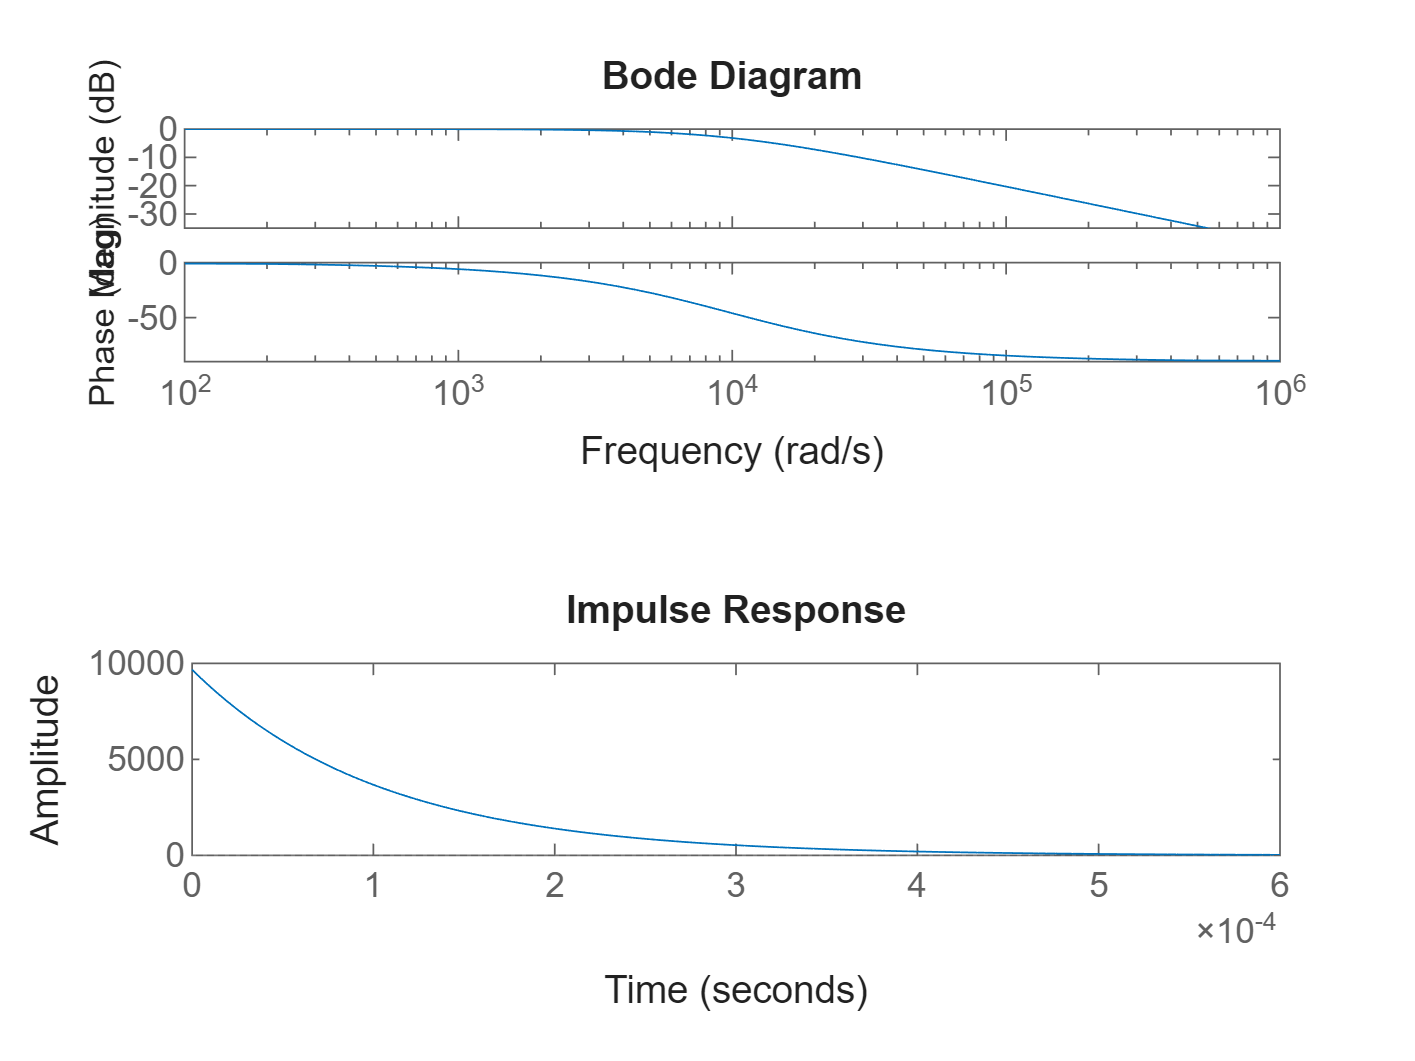

bode(sys)

-3dB threshold at 9.67e03 rad/s, so 1.5390 kHz

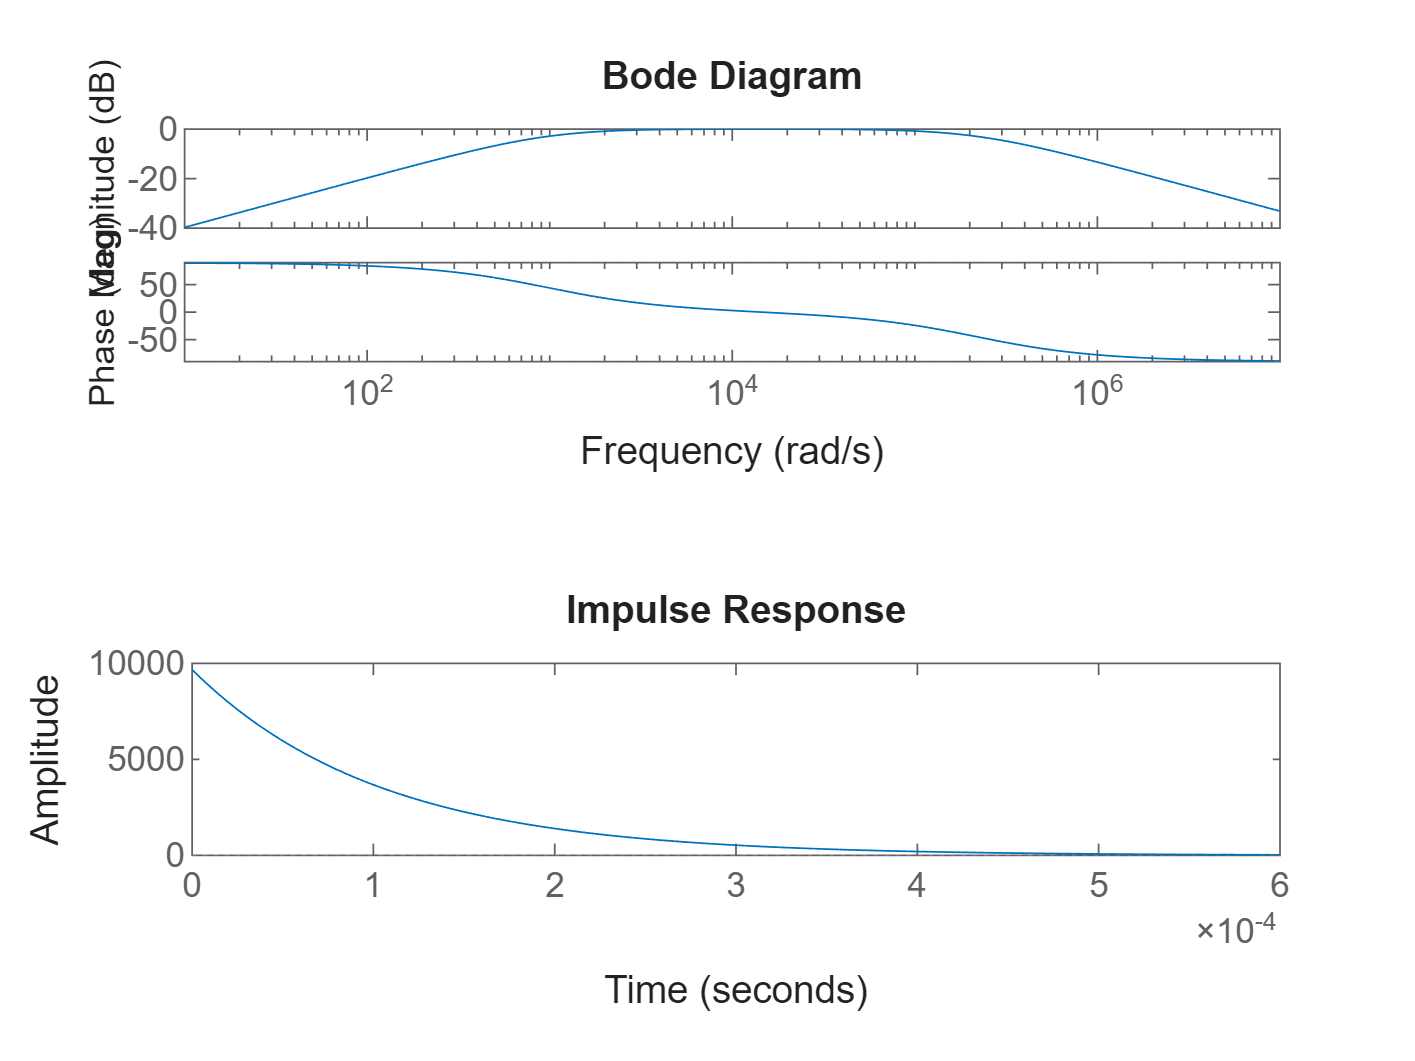

bode(sys2)

attenuation grater than -3bB between 913 rad/s and 23.3k rad/s

w1=913;
w2=2.33e05;
wr=1.46e04;
damping = (w2-w1)/(2*wr)

damping = 7.9482

Signal analysys:

A1(isnan(A1)) = 0;
B1(isnan(B)) = 0;
A2(isinf(A2)) = 0;
B2(isinf(B2)) = 0;

B – measured input signal v(t)

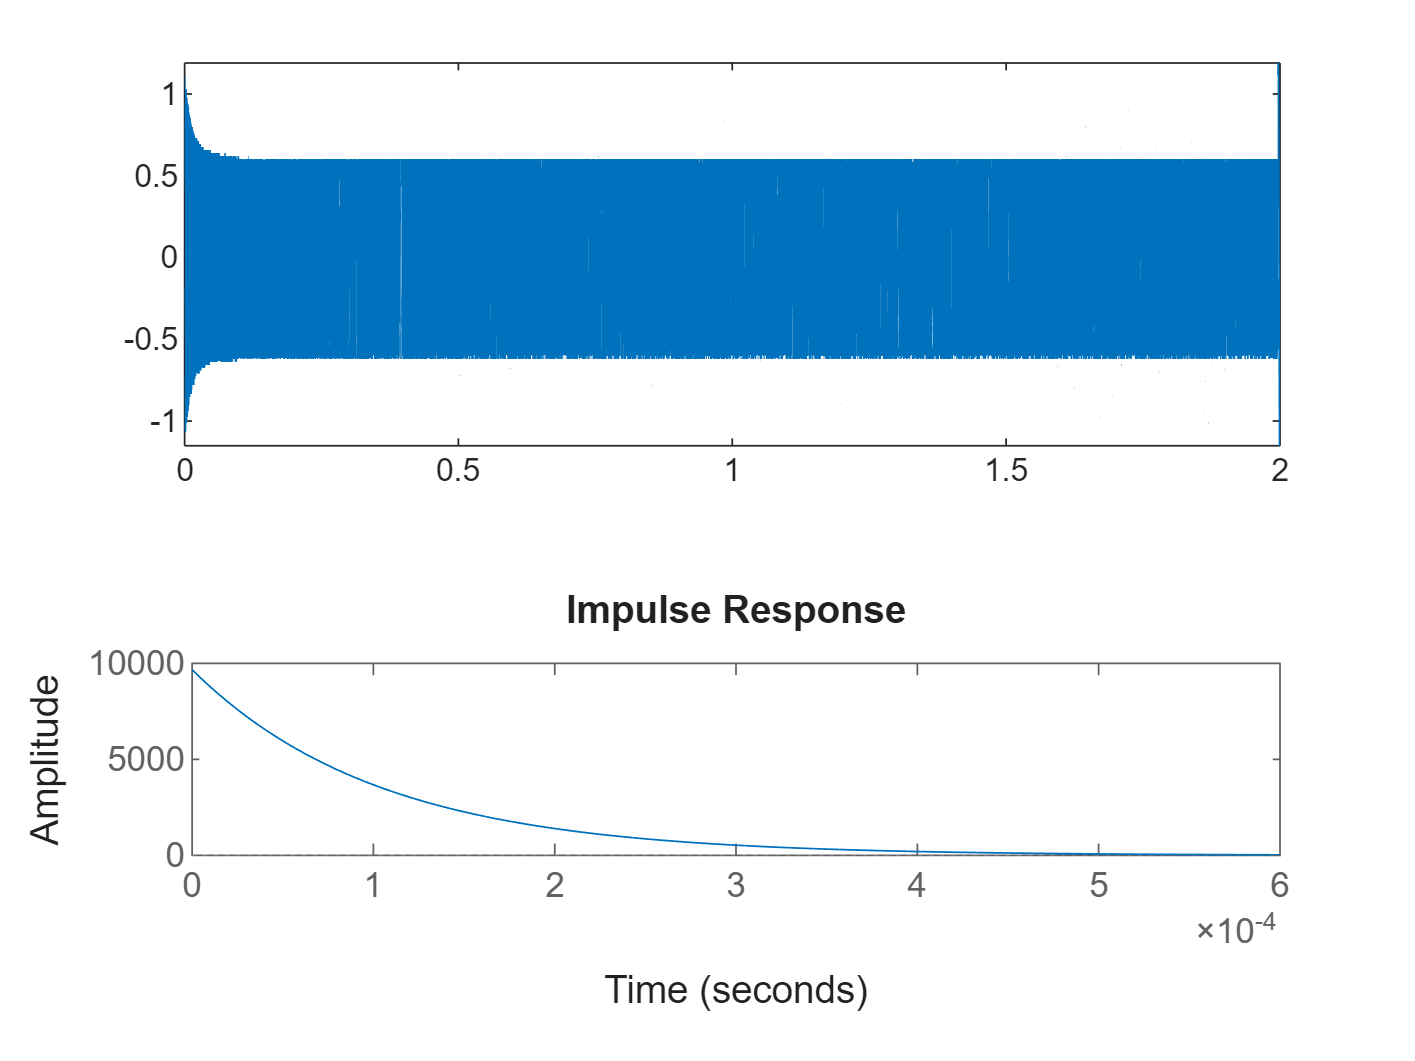

plot(t,B1)

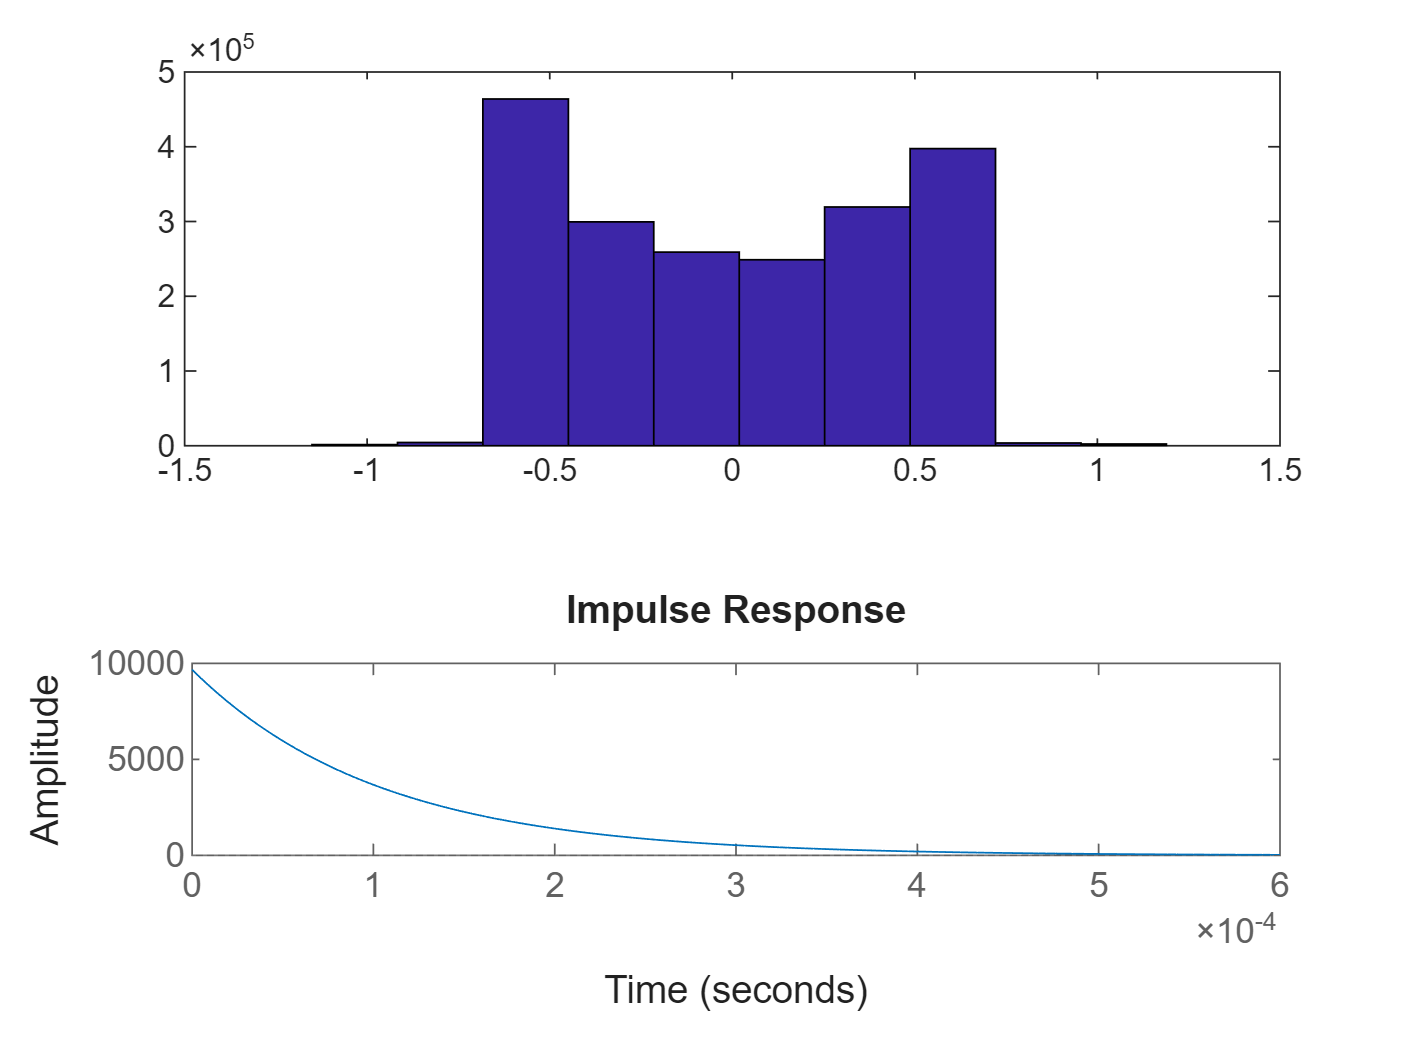

hist(B1)

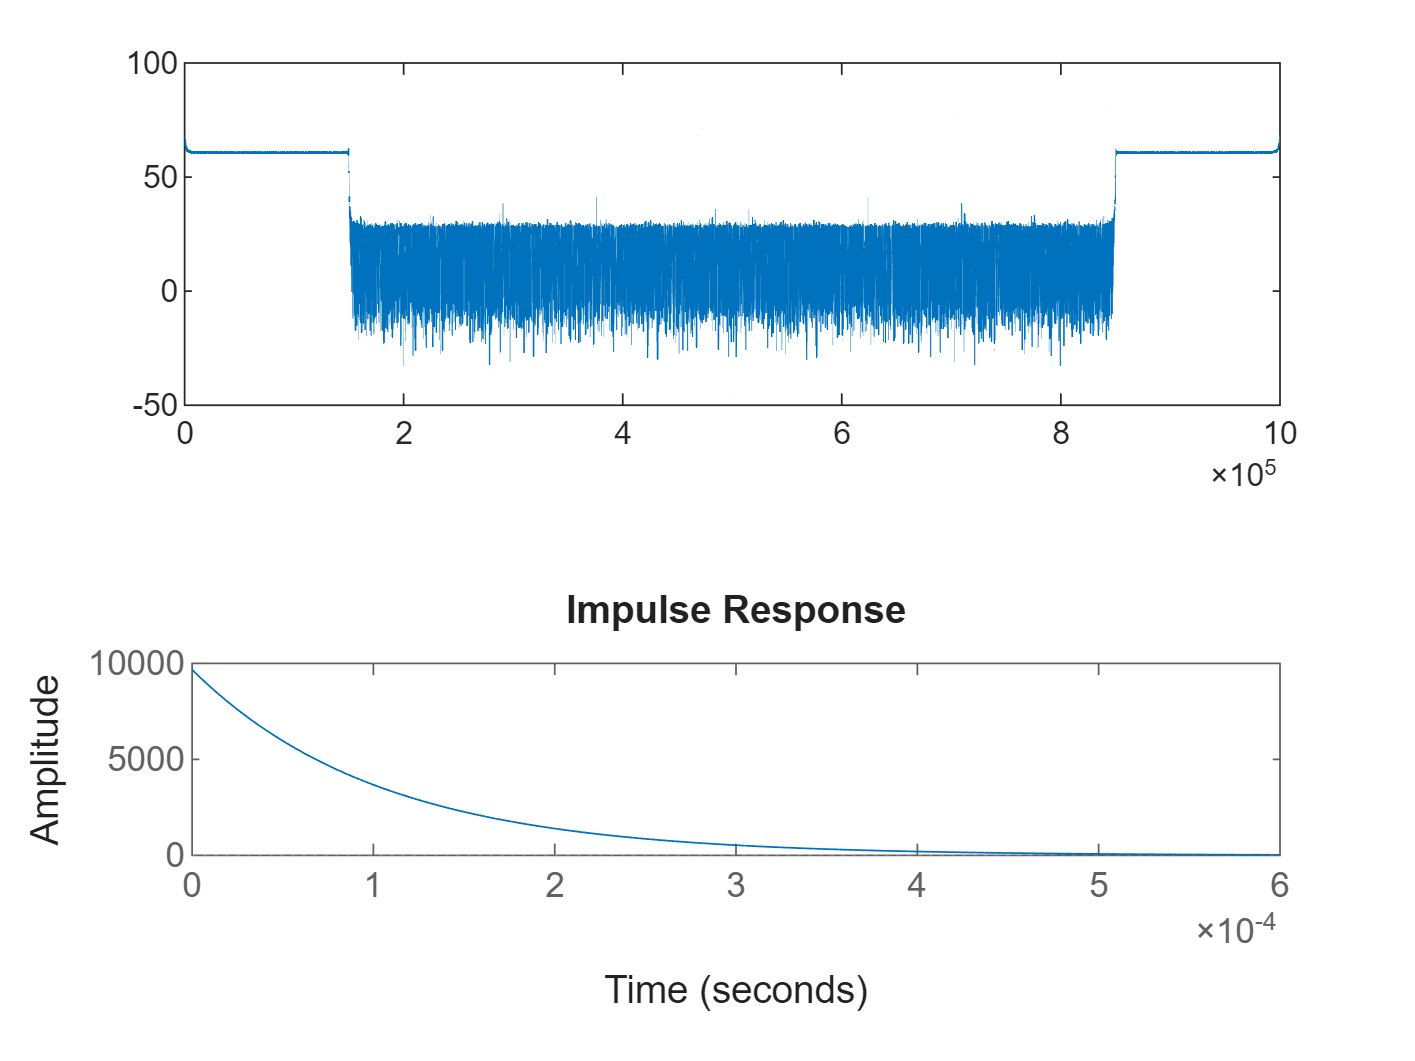

plot(f,20*log10(abs(fft(B1))))

A – measured output signal y(t)

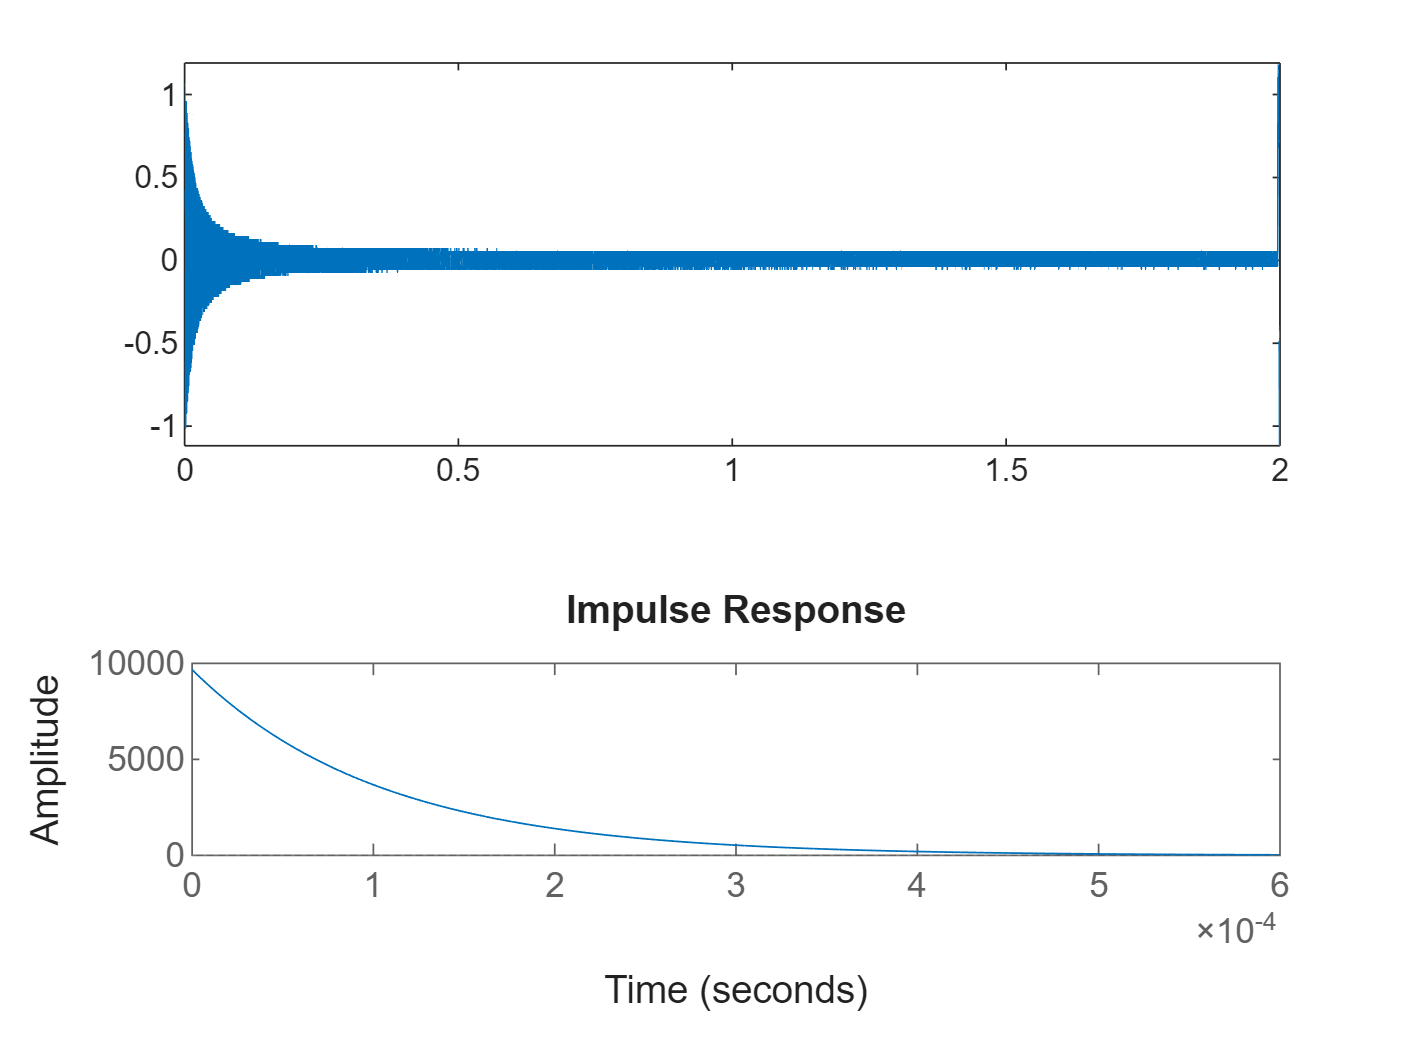

plot(t,A1)

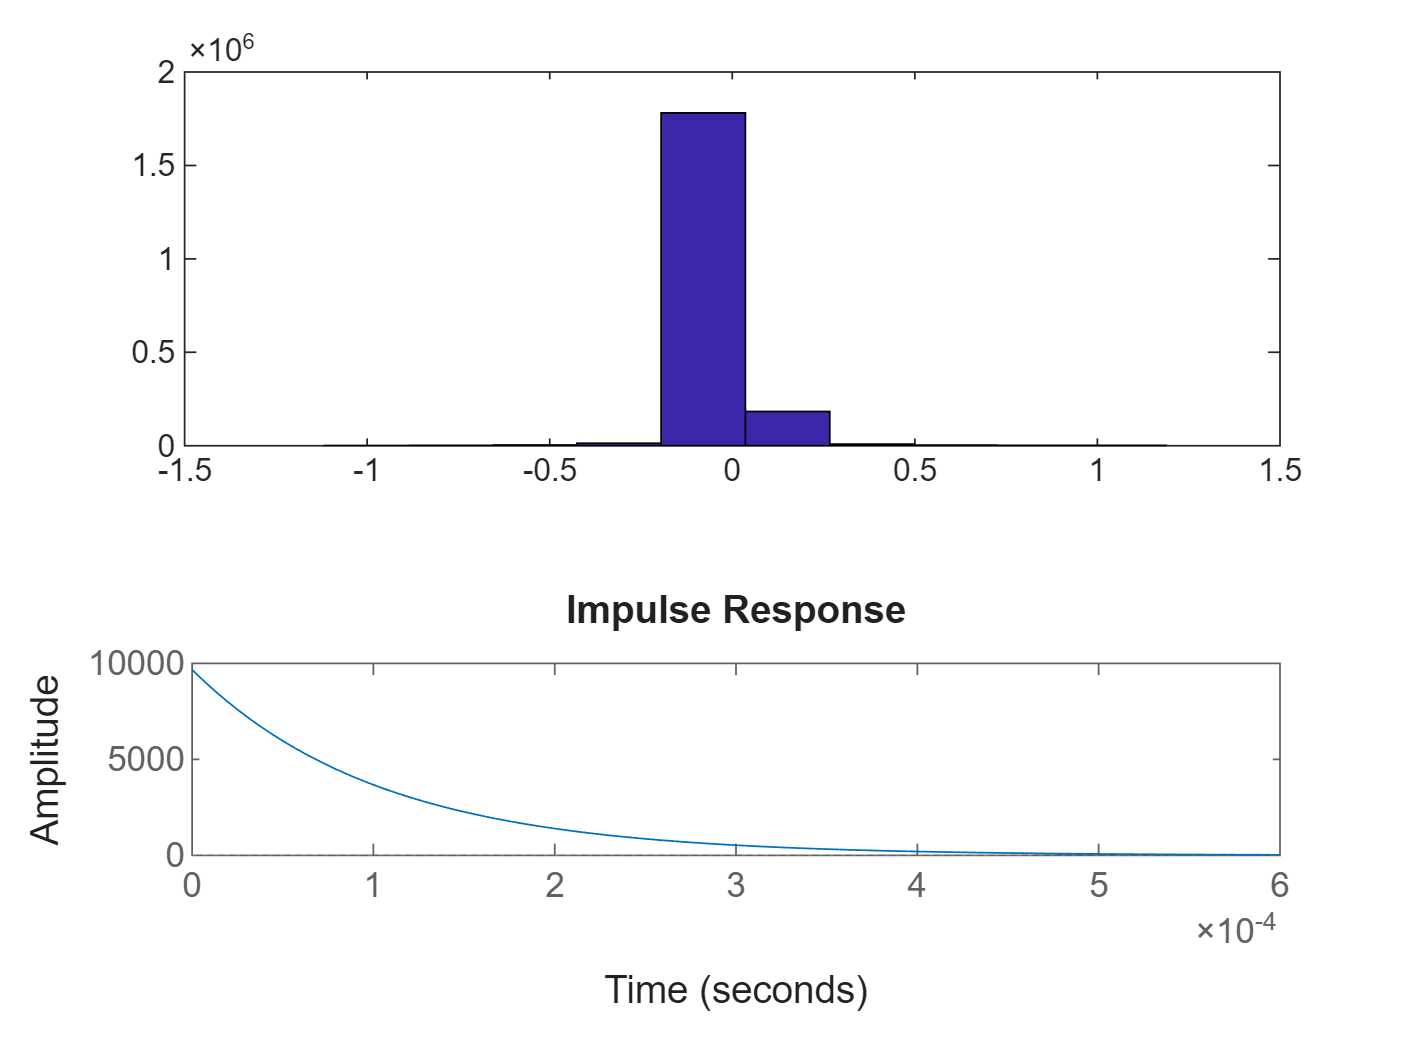

hist(A1)

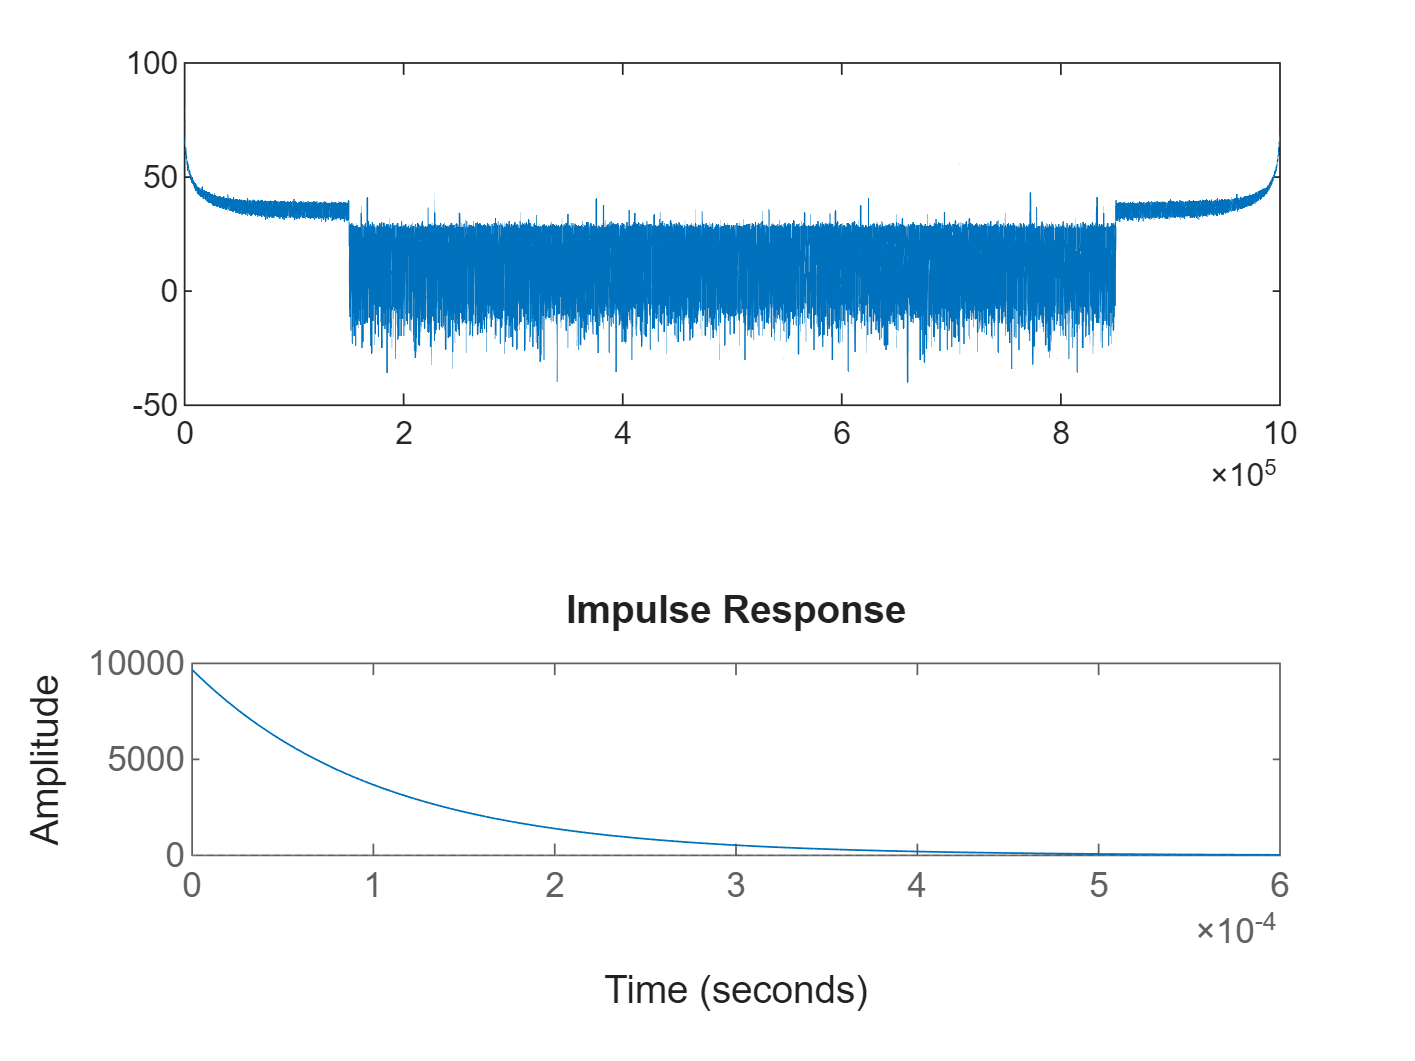

plot(f,20*log10(abs(fft(A1))))

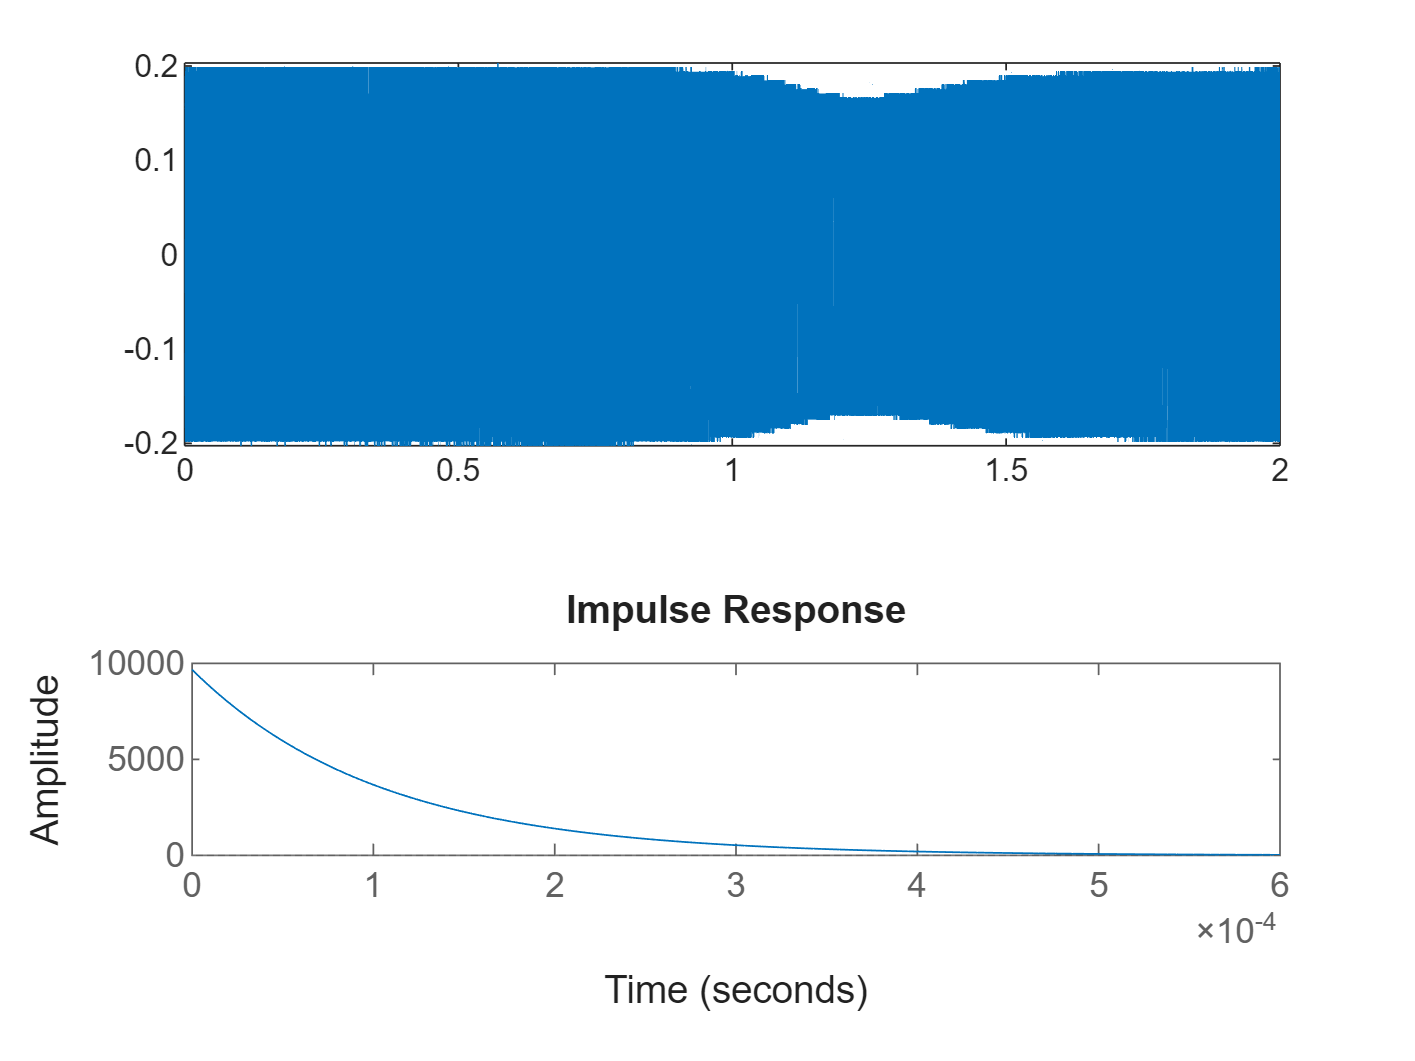


plot(t,B2)

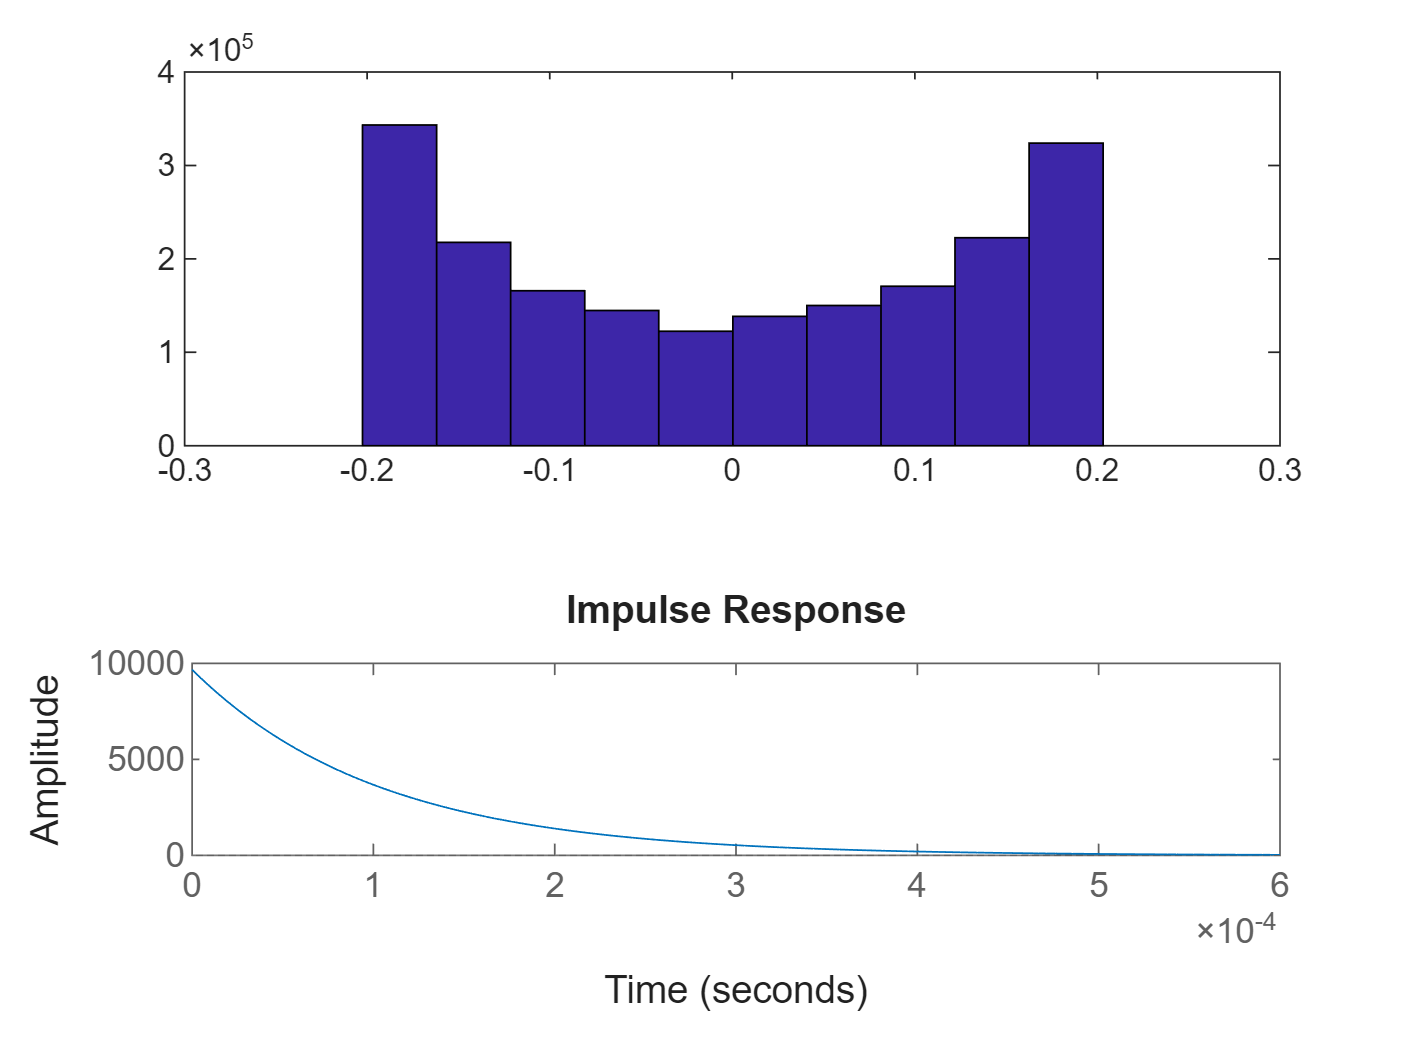

hist(B2)

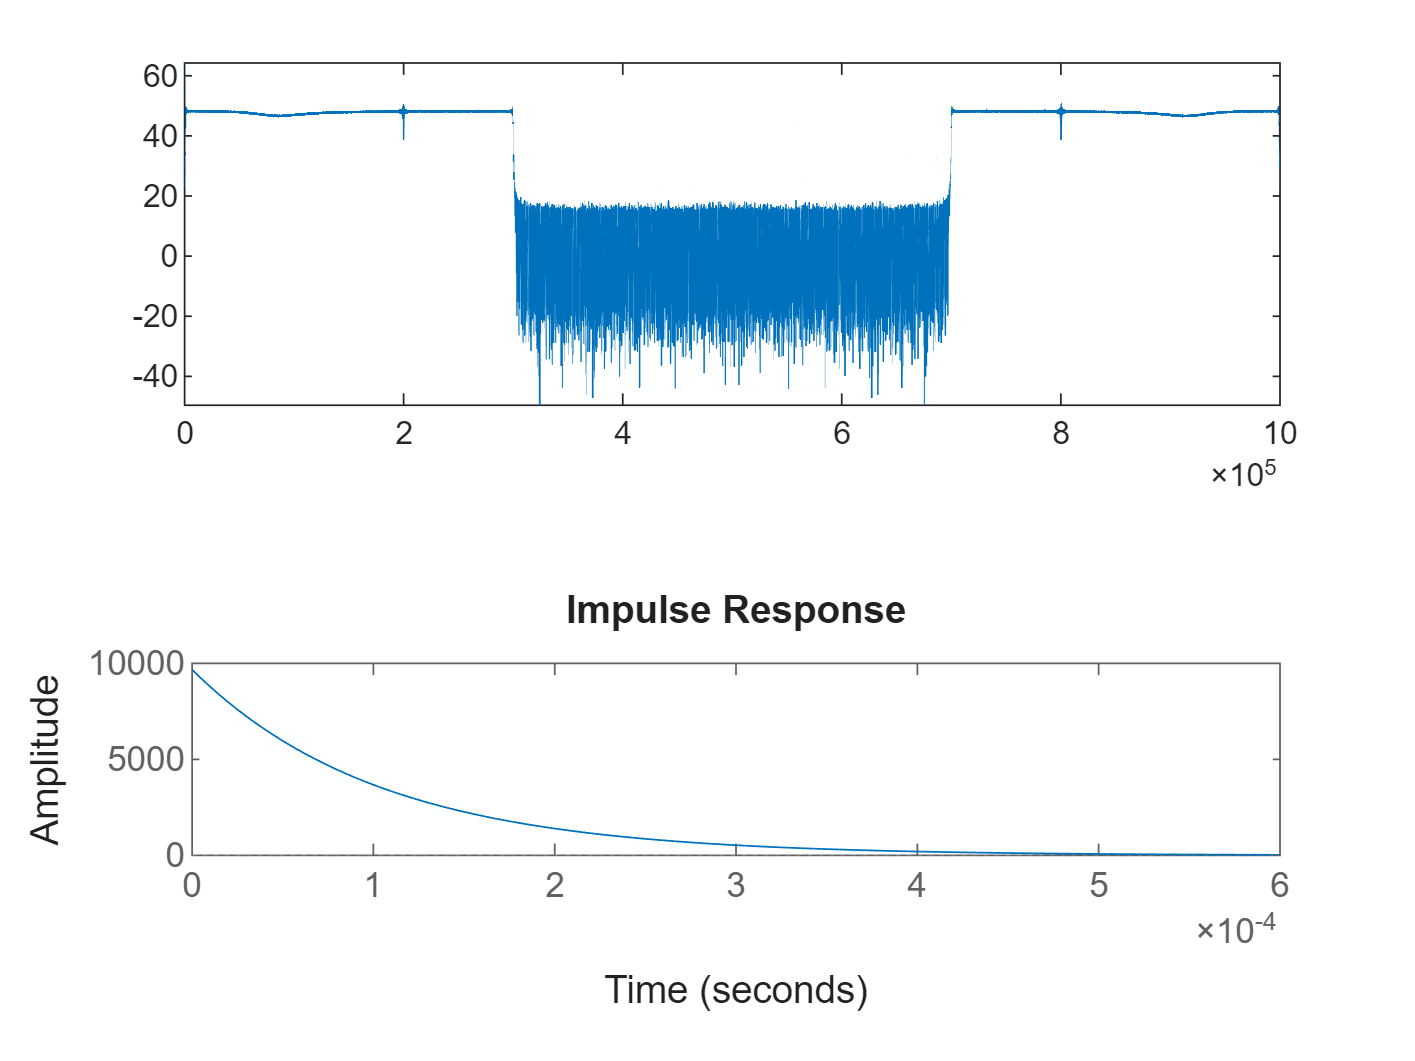

plot(f,20*log10(abs(fft(B2))))

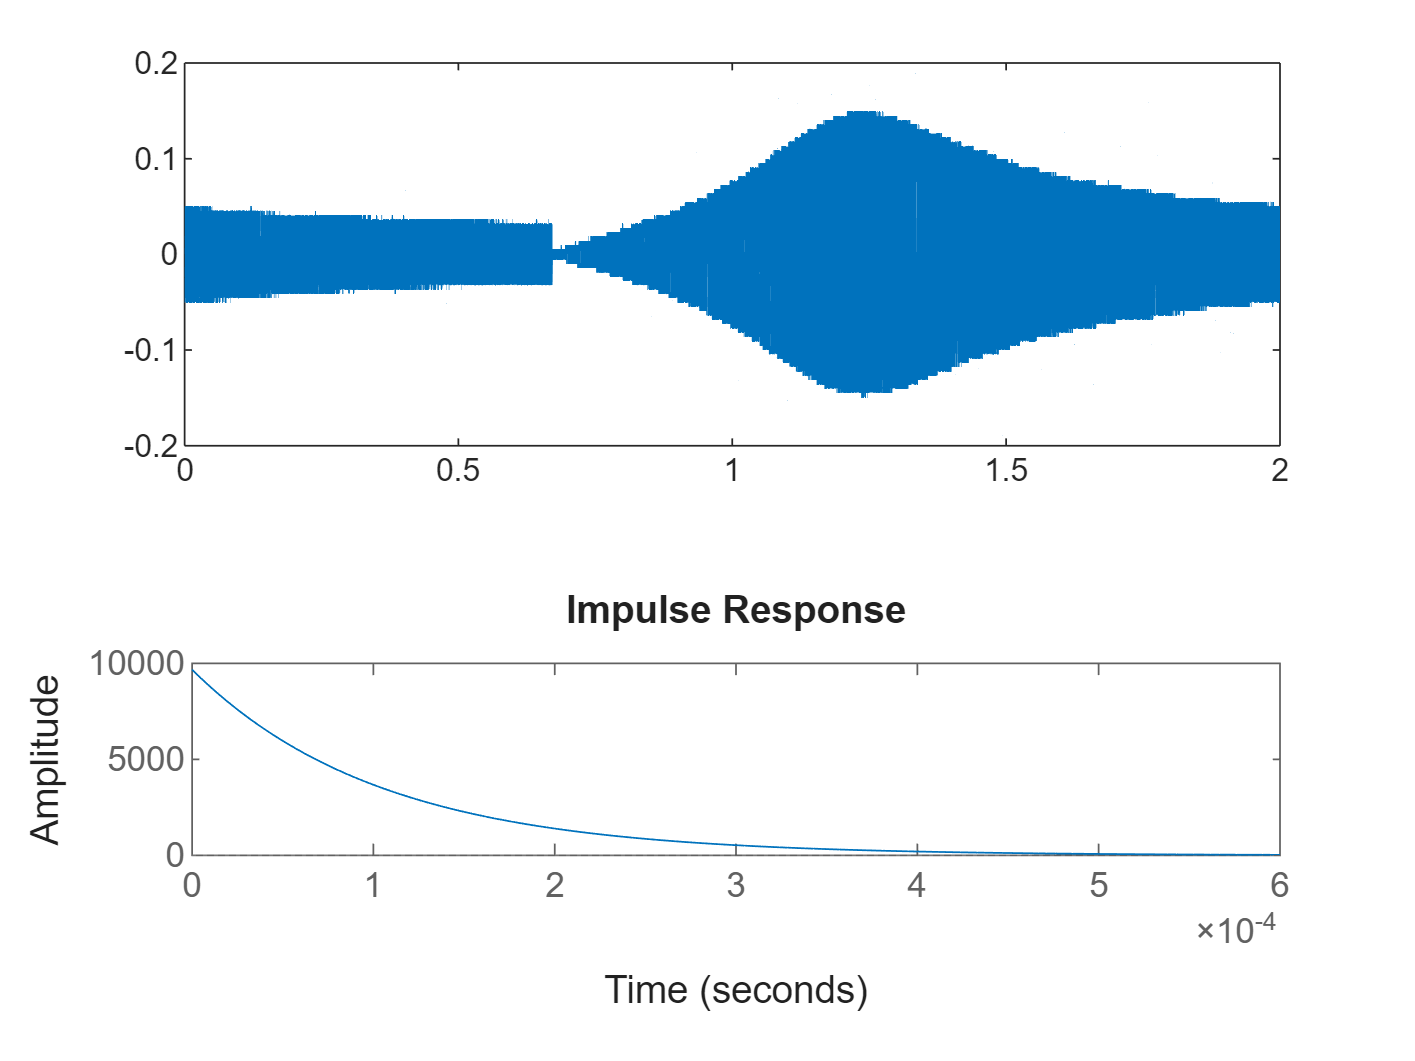

plot(t,A2)

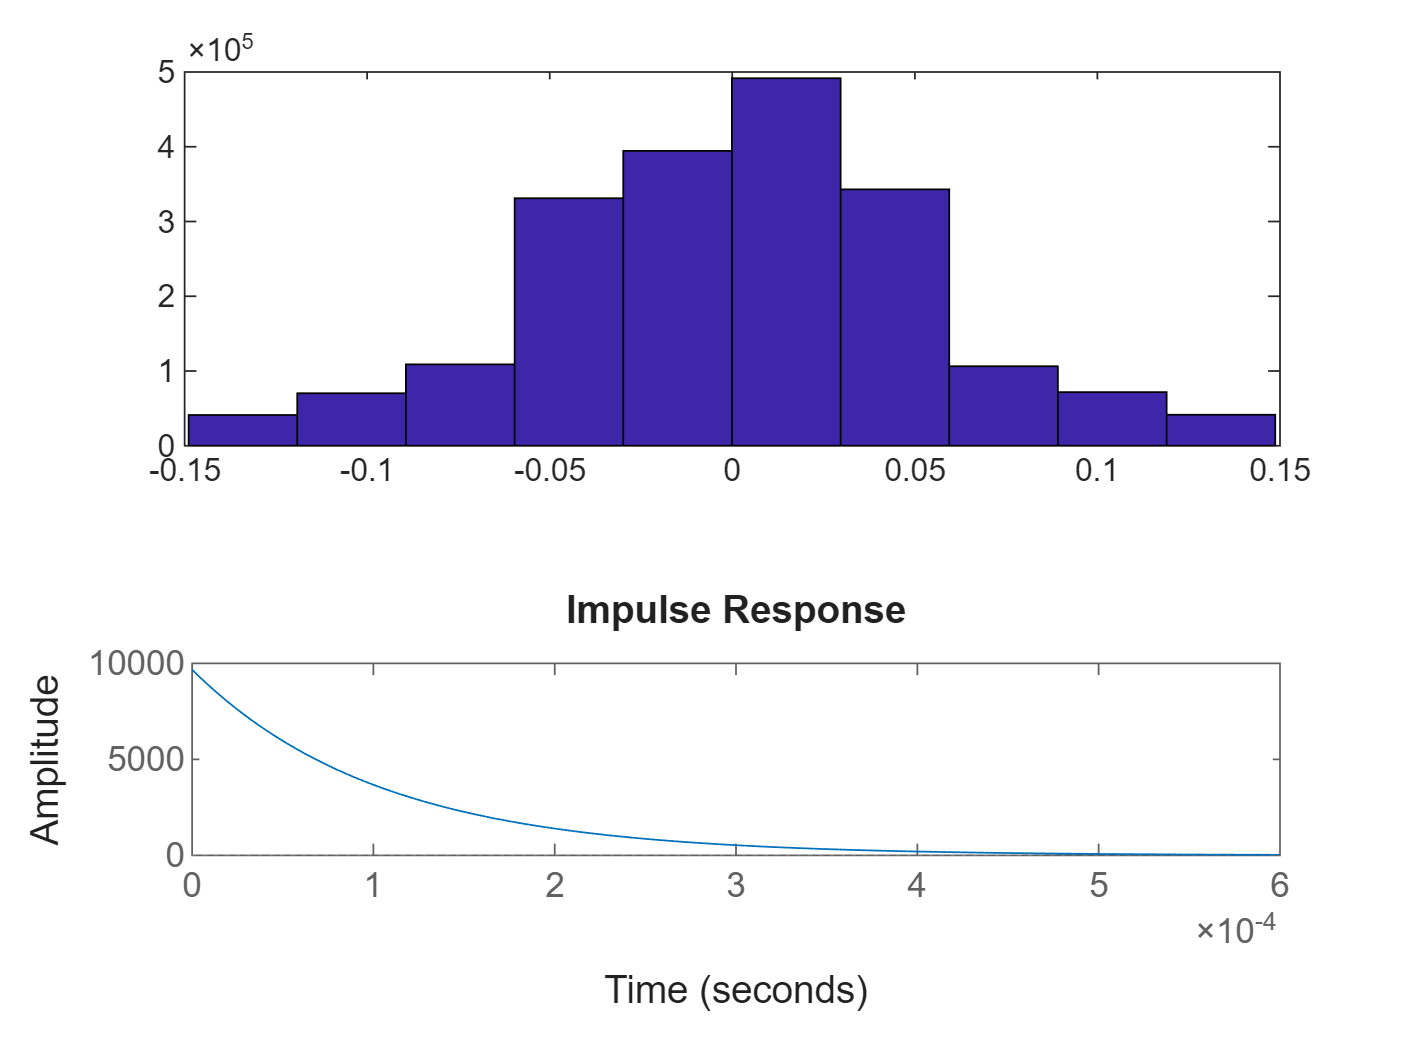

hist(A2)

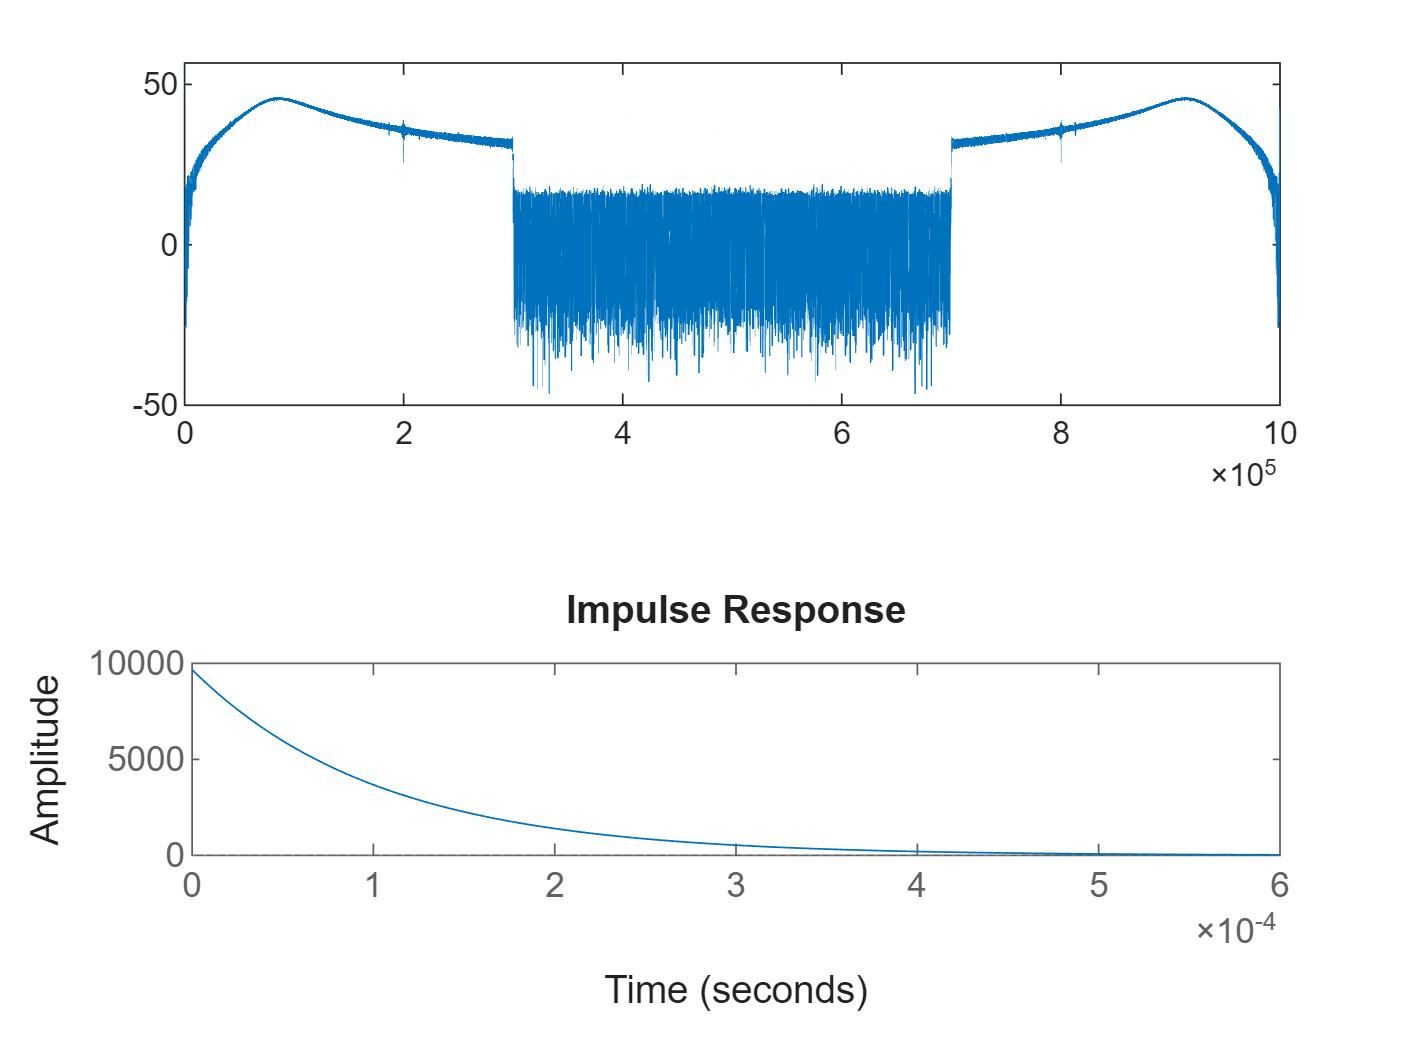

plot(f,20*log10(abs(fft(A2))))

## Ex.1.1

Creating system response Y(w) for chirp input V(w)

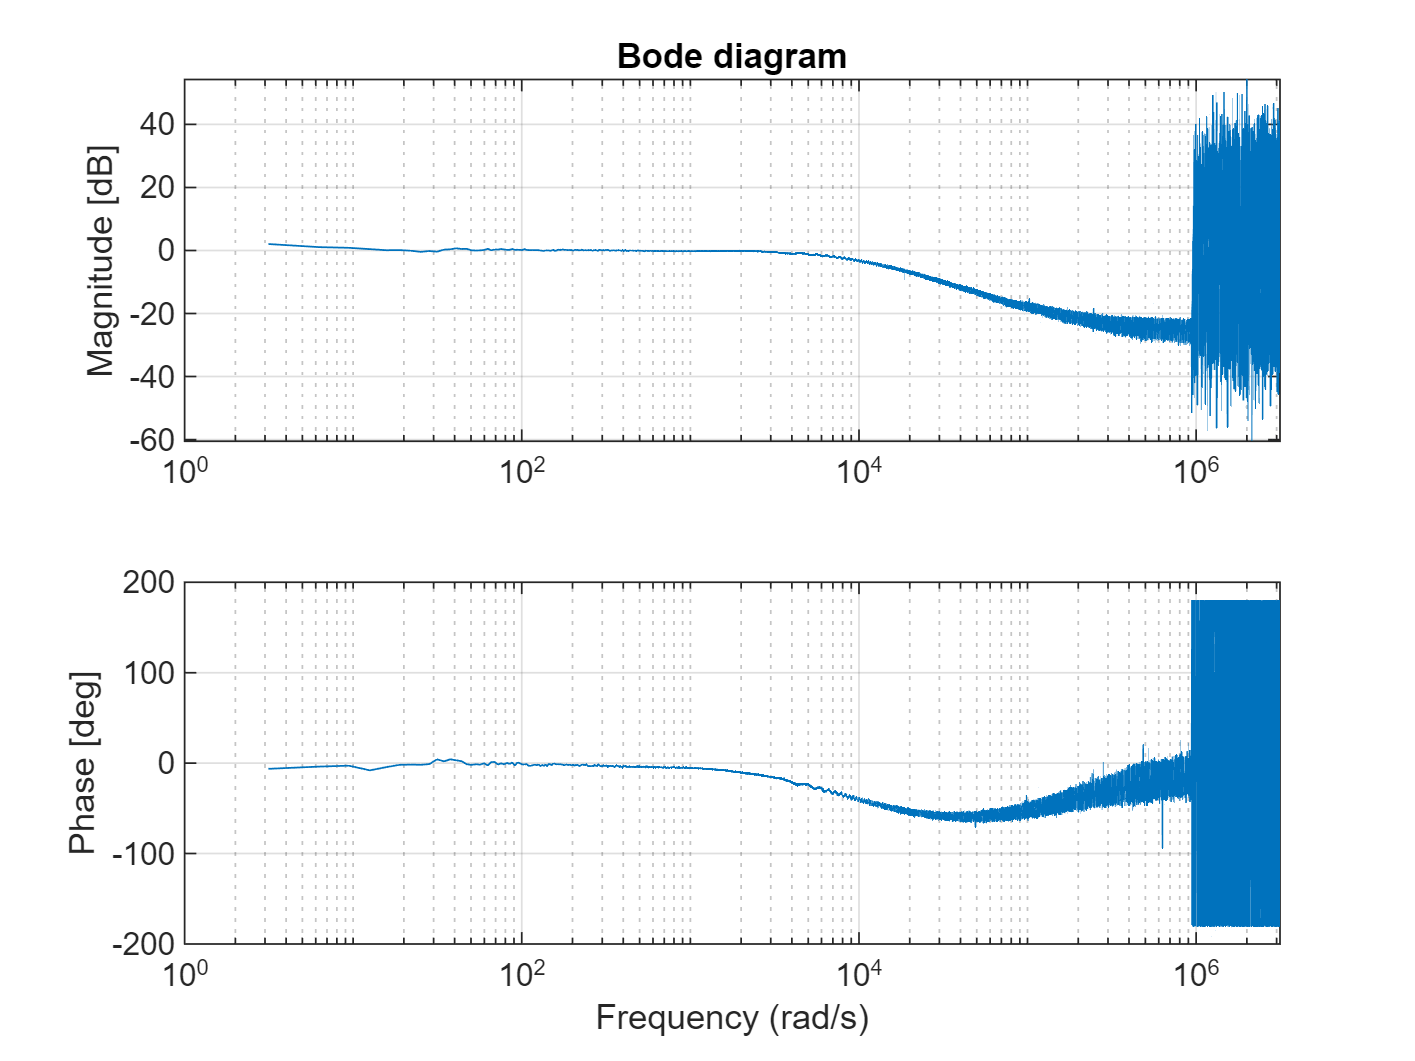

ownBode(B1,A1,fs)

This looks like a lowpass of sorts up till 940k rad/s where weird stuff happen

We see attenuation of -3dB at around 10k rad/s which is consistent with matlab bode plot of the lowpass filter

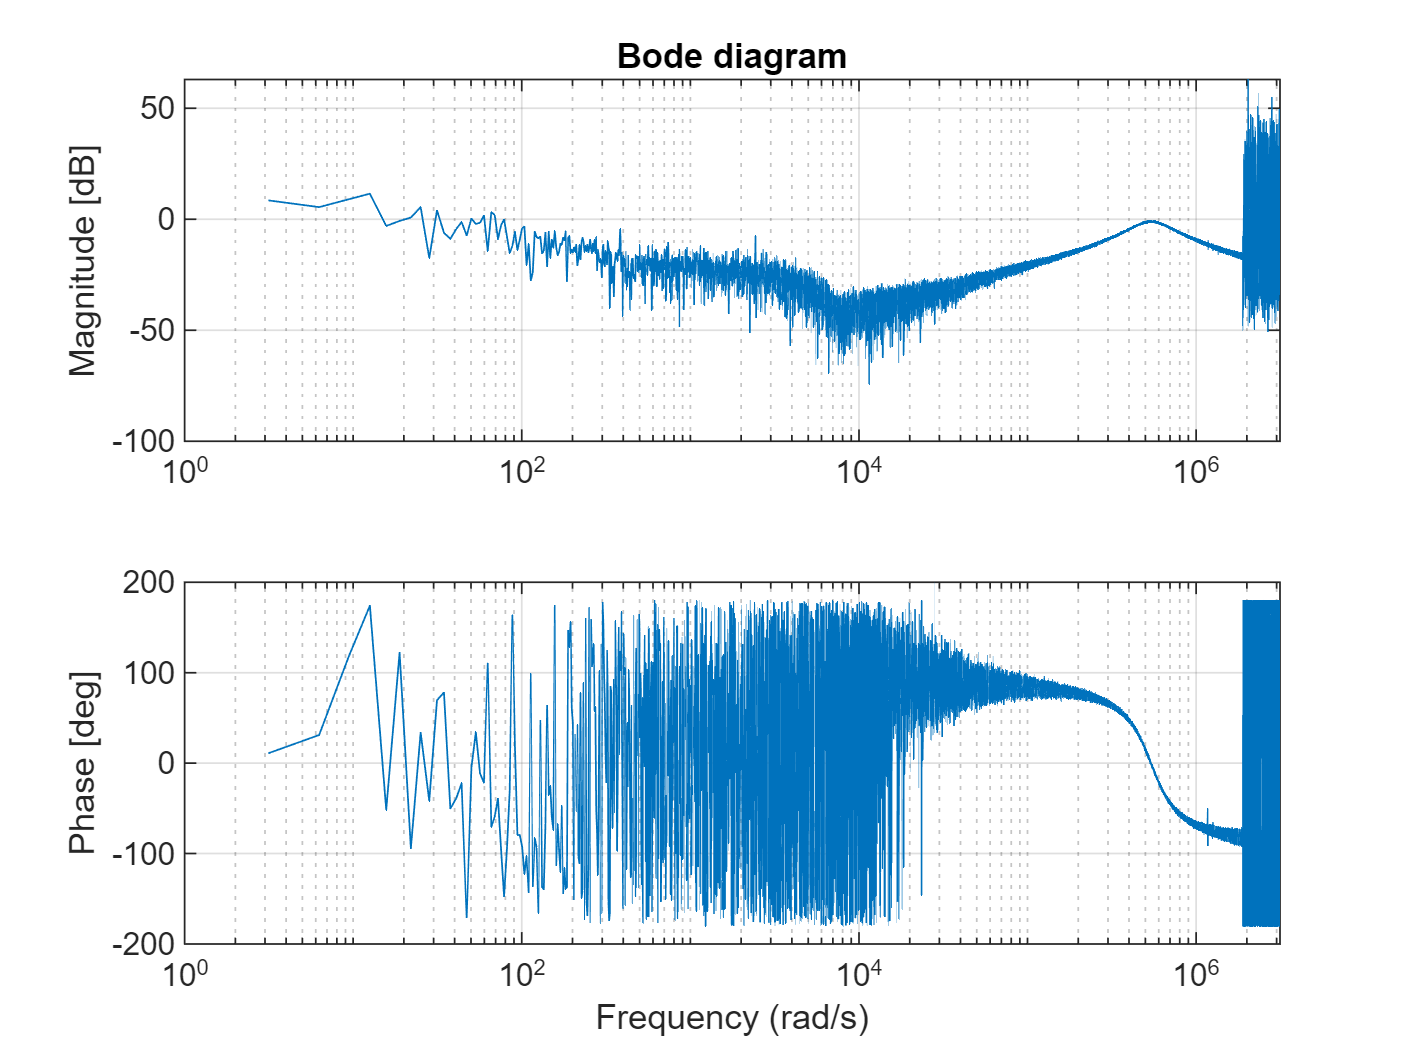

ownBode(B2,A2,fs)

We see that attenuation starts at 85 rad/s and comes back above -3dB at 42.5k rad/s. This range is far wider than the bode plot of the filter would indicate.

peak of -0.719dB at 5.479e05rad/s

w1=4.1e05

w1 = 410000

w2=7.1e05

w2 = 710000

damping2=(7.1-4.1)/(2*5.479)

damping2 = 0.2738

Here the calculated damping is significantly lower than calculated on the theoritical bode of our system





function ownBode(x1,y1,fs)

N=length(x1);
X=fft(x1);
Y=fft(y1);
H=Y./X;
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-df);
figure
title('Bode diagram')
subplot(211)
semilogx(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')
grid on
% xlim([10e3,10e6]);
ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
semilogx(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))
% xlim([10e3,10e6]);
grid on
ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')
end